%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data, including data with all flags
%SDK
ppbSDK = readtimetable("ppb SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSDKnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSDKnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKATEC = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ppbSDKATECnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ppbSDKATECnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKEnt = readtimetable("ppb SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ppbSDKEntnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ppbSDKEntnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

%STER
ppbSTER = readtimetable("ppb STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSTERnoLK = readtimetable("ppb STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSTERnoHg = readtimetable("ppb STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ppbSSG = readtimetable("ppb SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSSGnoLK = readtimetable("ppb SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSSGnoHg = readtimetable("ppb SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%COV
ppbCOV = readtimetable("ppb COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbCOVnoLK = readtimetable("ppb COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbCOVnoHg = readtimetable("ppb COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
cd ..

%SDK, AROMA
ppbAROMA = readtimetable("etoAROMA_SDK.xlsx");

cd ../.. %return to data folder

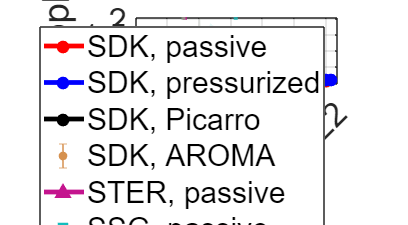

%%%%%%%%%%%%%%%%%%%%%%
%%%PLOT FIGURE TIMESERIES
%%%%%%%%%%%%%%%%%%%%%%

fig = figure('Position', get(0, 'Screensize')); %for saving the figure

%%%a. Time Series
%%%INPUTS
dataSDKEnt = ppbSDKEnt;
dataSDKATEC = ppbSDKATEC;
dataSDKPicarro = ppbSDKPicarro;
dataSTER = ppbSTER;
dataSSG = ppbSSG;
dataCOV = ppbCOV;
colorSTER = [0.769, 0.080, 0.557];
colorSSG = [0.071, 0.74, 0.74];
colorCOV = [122, 142, 117]/255;
colorAROMA = [0.8392, 0.5686, 0.3098];
controlsSTER = datetime(2020, 4, 8);
controlsSSG = datetime(2021, 1, 26);
controlsCOV = datetime(2020, 3, 31);
colors = [1, 0, 0; 0, 0, 1; 0, 0, 0; colorAROMA; colorSTER; colorSSG; colorCOV];
xlims = datetime([2019, 2022], [7, 9], 1);
xtickss = xlims(1):calmonths(6):datetime(2022, 7, 1);
ylims = [-0.05, 2.05];
ytickss = 0:0.5:2;

%%plot
ax = gca;
hold on
grid on
box on

hl = gobjects(7, 1);

%SDK, passive
dataMonthSDKEnt = binByMonth(dataSDKEnt); %upwind STER, bin by month
times = datenum(dataMonthSDKEnt.Properties.RowTimes); %grab date nums
[hl(1), hp] = boundedline(times, dataMonthSDKEnt.avgs, dataMonthSDKEnt.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colors(1, :));
hl(1).MarkerSize = 6; %change line aspects
hl(1).MarkerFaceColor = colors(1, :);
hl(1).LineWidth = 3.5;

%SDK, pressurized
dataMonthSDKATEC = binByMonth(dataSDKATEC); %upwind STER, bin by month
times = datenum(dataMonthSDKATEC.Properties.RowTimes); %grab date nums
[hl(2), hp] = boundedline(times, dataMonthSDKATEC.avgs, dataMonthSDKATEC.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colors(2, :));
hl(2).MarkerSize = 6; %change line aspects
hl(2).MarkerFaceColor = colors(2, :);
hl(2).LineWidth = 3.5;

%SDK, Picarro
dataMonthSDKPicarro = binByMonth(dataSDKPicarro); %upwind STER, bin by month
times = datenum(dataMonthSDKPicarro.Properties.RowTimes); %grab date nums
[hl(3), hp] = boundedline(times, dataMonthSDKPicarro.avgs, dataMonthSDKPicarro.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colors(3, :));
hl(3).MarkerSize = 6; %change line aspects
hl(3).MarkerFaceColor = colors(3, :);
hl(3).LineWidth = 3.5;

%SDK, AROMA
hl(4) = errorbar(datenum(datetime(2022, 7, 1)), mean(ppbAROMA.EtO, "omitnan"), ...
    std(ppbAROMA.EtO, 0, "omitnan"), 'o', 'color', colors(4, :));
hl(4).MarkerSize = 9.5; %change line aspects
hl(4).MarkerFaceColor = colors(4, :);

%STER
dataMonthSTER = binByMonth(dataSTER); %upwind STER, bin by month
times = datenum(dataMonthSTER.Properties.RowTimes); %grab date nums
[hl(5), hp] = boundedline(times, dataMonthSTER.avgs, dataMonthSTER.stds, ...
    '^-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colorSTER);
hl(5).MarkerSize = 6; %change line aspects
hl(5).MarkerFaceColor = colorSTER;
hl(5).LineWidth = 3.5;

%SSG
dataMonthSSG = binByMonth(dataSSG); %upwind SSG, bin by month
times = datenum(dataMonthSSG.Properties.RowTimes); %grab date nums
[hl(6), hp] = boundedline(times, dataMonthSSG.avgs, dataMonthSSG.stds, ...
    'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colorSSG);
hl(6).Marker = "square";
hl(6).MarkerSize = 7; %change line aspects
hl(6).MarkerFaceColor = colorSSG;
hl(6).LineWidth = 3.5;

%COV
dataMonthCOV = binByMonth(dataCOV); %upwind COV, bin by month
times = datenum(dataMonthCOV.Properties.RowTimes); %grab date nums
[hl(7), hp] = boundedline(times, dataMonthCOV.avgs, dataMonthCOV.stds, ...
    'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colorCOV);
hl(7).Marker = "diamond";
hl(7).MarkerSize = 7; %change line aspects
hl(7).MarkerFaceColor = colorCOV;
hl(7).LineWidth = 3.5;

%controls lines
xline(datenum(controlsSTER), '--', "linewidth", 3, ...
    "color", colorSTER) %STER
xline(datenum(controlsSSG), '--', "linewidth", 3, ...
    "color", colorSSG) %SSG
xline(datenum(controlsCOV), '--', "linewidth", 3, ...
    "color", colorCOV*1.2) %COV

%move lines to top
uistack(hl(1), 'top')
uistack(hl(2), 'top')
uistack(hl(3), 'top')
uistack(hl(5), 'top')
uistack(hl(6), 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "mmm yyyy");
ylim(ylims)
yticks(ytickss)

%%labels
pbaspect([3, 1, 1])
ax.FontSize = 25;
xlabel("Local Time (EST)")
ylabel("EtO (ppb)")
legend(hl(:), "SDK, passive", "SDK, pressurized", "SDK, Picarro",...
    "SDK, AROMA", "STER, passive", "SSG, passive", "COV, passive")
% legend("", "", "", "", "", "", "", "SDK, passive", "SDK, pressurized", ...
%     "SDK, Picarro", "STER, passive", "SSG, passive", "location", "northeast");

hold off

% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Figure 2.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data

%%%%%%%%%%%%%%%%%%%%%%
%%%evaluate change in trend in 2021
%%%%%%%%%%%%%%%%%%%%%%

changeInTrendTime = datetime(2021, 1, 2); %time to compare
toAverageDataMonth = {dataMonthSDKEnt, dataMonthSSG, dataMonthSTER, dataMonthCOV}; %all TO-15 passive
meansBefore = []; %monthly mean before change
meansAfter = []; %monthly mean after change
stdsBefore = []; %monthly std before change
stdsAfter = []; %monthly std after change

for i = 1:length(toAverageDataMonth) %iterate through each dataset
    current = toAverageDataMonth{i};
    times = current.Properties.RowTimes;
    inds = times <= changeInTrendTime; %identify time before change

    %%file into means and stds
    meansBefore = [meansBefore; mean(current.avgs(inds), "omitnan")];
    meansAfter = [meansAfter; mean(current.avgs(~inds), "omitnan")];
    stdsBefore = [stdsBefore; mean(current.stds(inds), "omitnan")];
    stdsAfter = [stdsAfter; mean(current.stds(~inds), "omitnan")];
end

changeMeans = (meansAfter - meansBefore)./meansBefore;
mean(changeMeans, "omitnan")

ans = -0.4059

changeStds = (stdsAfter - stdsBefore)./stdsBefore;
mean(changeStds, "omitnan")

ans = -0.5314